clear all
clf
format shortg
% data = xlsread("Statestik\Eksamens sæt\21E\Data_M4STI1_2021E.xlsx");

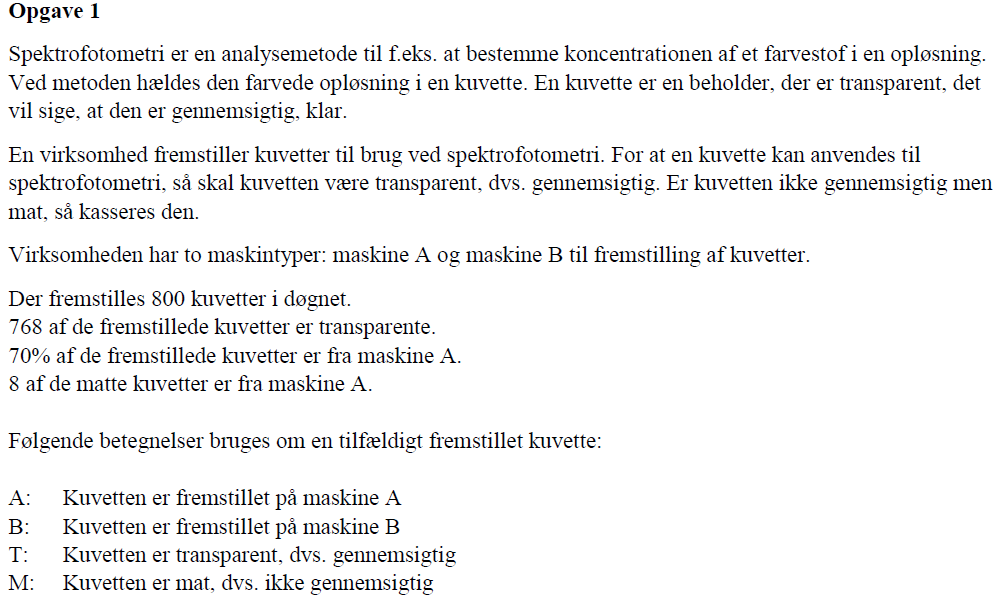

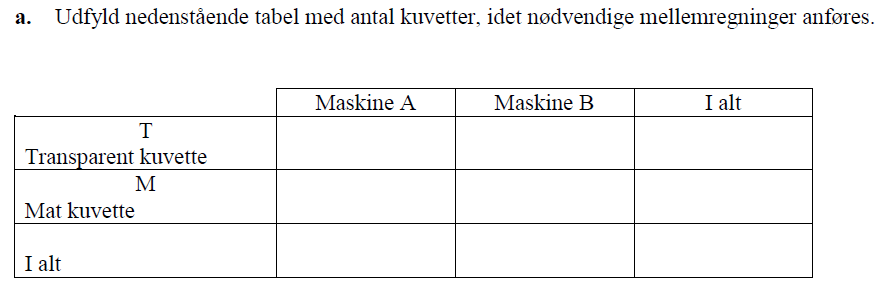

tot = 800

tot =    800


tot_T = 768

tot_T =    768


tot_M = tot - tot_T

tot_M =     32


A_tot = 0.7 * tot

A_tot =    560


A_M = 8

A_M =      8


A_T = A_tot - A_M

A_T =    552


B_tot = tot - A_tot

B_tot =    240


B_T = tot_T - A_T

B_T =    216


B_M = tot_M - A_M

B_M =     24


Kol_names = {'Maskine A', ' Maskine B', 'I alt'};
row_names = {'T - Transparent kuvette', 'M - Mat kuvette', 'I alt'};
table([A_T; A_M; A_tot], [B_T; B_M; B_tot], [tot_T; tot_M; tot], VariableNames=Kol_names, RowNames=row_names)

ans = 3×3 table
                               Maskine A     Maskine B    I alt
                               _________    __________    _____

    T - Transparent kuvette       552          216         768 
    M - Mat kuvette                 8           24          32 
    I alt                         560          240         800 


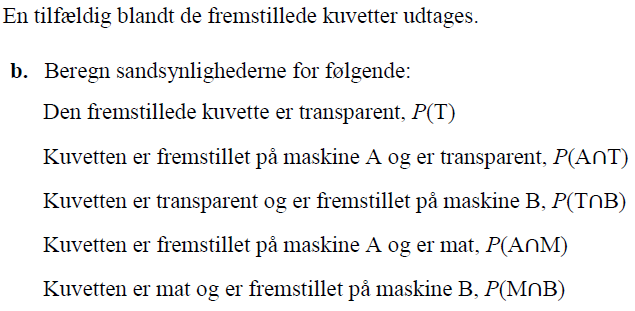

P_T = tot_T / tot

P_T =          0.96


P_A_fel_T = A_T/tot

P_A_fel_T =          0.69


P_T_fel_B = B_T/tot

P_T_fel_B =          0.27


P_A_fel_M = A_M/tot

P_A_fel_M =          0.01


P_M_fel_T = B_M/tot

P_M_fel_T =          0.03


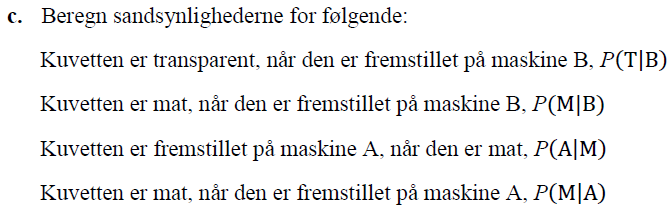

P_T_giv_B = B_T / B_tot

P_T_giv_B =           0.9


P_M_giv_B = B_M / B_tot

P_M_giv_B =           0.1


P_A_giv_M = A_M / tot_M

P_A_giv_M =          0.25


P_M_giv_A = A_M / A_tot

P_M_giv_A =      0.014286


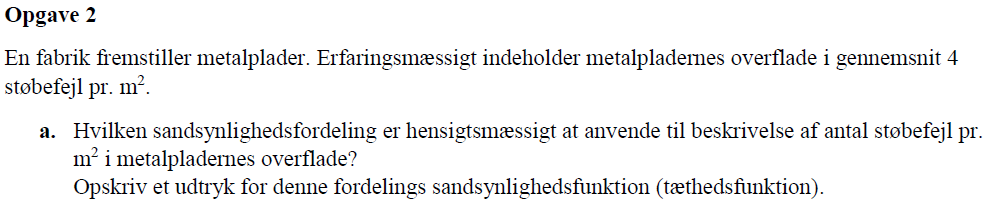

Possion fordelling vælges da den er disrket og der tælles fejl fra nul.

b. Bestem fordelingens middelværdi, varians og standardafvigelse.

lambda = 4 %middel værdi

lambda =      4


var = lambda %variansen

var =      4


std = sqrt(lambda) %standardafvigelsen

std =      2


P_3 = poisspdf(3,lambda)

P_3 =       0.19537


Sandsynligheden for 3 fejl er således 19,54%

d. Bestem sandsynligheden for at antallet af støbefejl er mindre eller lig med 6.

P_6kul = poisscdf(6,lambda)

P_6kul =       0.88933


Sandsynligheden for 6 fejl eller mindre er således 88,93%

e. Bestem sandsynligheden for at antallet af støbefejl er større eller lig med 7.

P_7kul_plus = 1 - P_6kul

P_7kul_plus =       0.11067


Sandsynligheden for 7 eller flere fejl er således 11,07%

f. Bestem sandsynligheden for at antallet af støbefejl ligger mellem 2 og 5.

P_2kul = poisscdf(2,lambda);
P_4kul = poisscdf(4,lambda);
P_25 = P_4kul - P_2kul

P_25 =       0.39073


**eller**

P_3pdf = poisspdf(3,lambda);
P_4pdf = poisspdf(4,lambda);
P_34 = P_3pdf + P_4pdf

P_34 =       0.39073


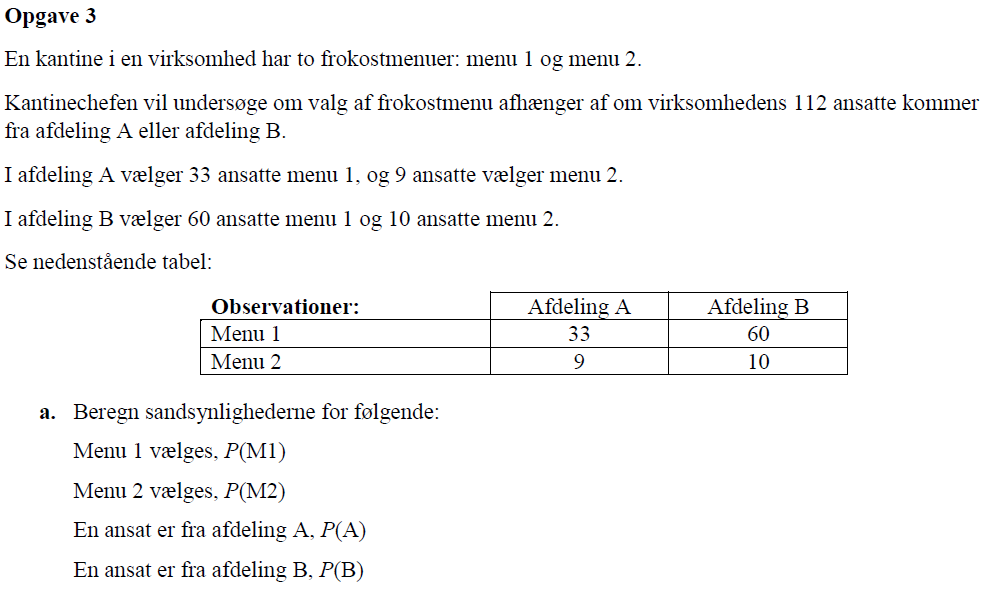

O_m1_A = 33;
O_m2_A = 9;
O_m1_B = 60;
O_m2_B = 10;

M1_tot = O_m1_A + O_m1_B

M1_tot =     93


M2_tot = O_m2_A + O_m2_B

M2_tot =     19


tot = M1_tot + M2_tot

tot =    112


P_M1 = M1_tot / tot

P_M1 =       0.83036


P_M2 = M2_tot / tot % eller 1 - P_M1

P_M2 =       0.16964


A_tot = 33 + 9

A_tot =     42


B_tot = 60 + 10

B_tot =     70


P_A = A_tot / tot

P_A =         0.375


P_B = B_tot / tot

P_B =         0.625


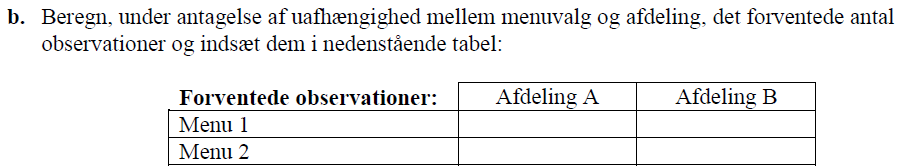

E_m1_A = tot * P_M1 * P_A

E_m1_A =        34.875


E_m1_B = tot * P_M1 * P_B

E_m1_B =        58.125


E_m2_A = tot * P_M2 * P_A

E_m2_A =         7.125


E_m2_B = tot * P_M2 * P_B

E_m2_B =        11.875



M_1 = E_m1_A + E_m1_B

M_1 =     93


M_2 = E_m2_A + E_m2_B

M_2 =     19




Kol_names = {'Afdeling A', ' Afdeling B', 'I alt'};
row_names = {'Menu 1', 'Menu 2', 'I alt'};
table(round([E_m1_A; E_m2_A; E_m1_A+ E_m2_A],0), round([E_m1_B; E_m2_B; E_m1_B + E_m2_B],0), round([M_1; M_2; tot],0), VariableNames=Kol_names, RowNames=row_names)

ans = 3×3 table
              Afdeling A     Afdeling B    I alt
              __________    ___________    _____

    Menu 1        35            58           93 
    Menu 2         7            12           19 
    I alt         42            70          112 


c. Opstil nulhypotese og alternativ hypotese for hypotesetesten.

$H_0:$ valg af menu er uafhængig af afdeling

$H_a:$ valg af menu er afhængig af afdeling

d. Opstil en formel for teststørrelsen (teststatistikken), og angiv hvilken fordeling den følger.

Da der testes for uafhængighed benyttes en Chi i anden test:

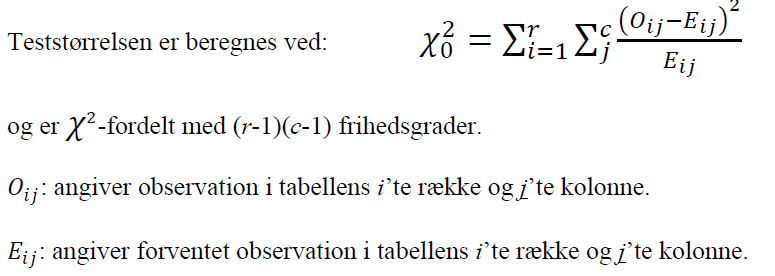

e. Bestem den kritiske værdi og angiv det kritiske område for testen, når der vælges et signifikansniveau på 5%.

alpha = 1 - 0.05

alpha =          0.95


df = (2 - 1) * (2 - 1) % en to gange to matrix estameres 

df =      1


chi2inv(alpha, df)

ans =        3.8415


Vi forskater $H_0$ hvis $\chi^2 > 3,8415$ 

f. Beregn teststørrelses (teststatistikkens) værdi. Mellemregninger skal fremgå.

chi2_M1_A = (O_m1_A - E_m1_A)^2 / E_m1_A

chi2_M1_A =       0.10081


chi2_M2_A = (O_m2_A - E_m2_A)^2 / E_m2_A

chi2_M2_A =       0.49342


chi2_M1_B = (O_m1_B - E_m1_B)^2 / E_m1_B

chi2_M1_B =      0.060484


chi2_M2_B = (O_m2_B - E_m2_B)^2 / E_m2_B

chi2_M2_B =       0.29605


chi2_test = chi2_M1_A + chi2_M2_A + chi2_M1_B + chi2_M2_B

chi2_test =       0.95076


g. Konkluder på hypotesetesten.

Det ses at $1,088 < 3,8415$ og vi er kan således ikke forkaste vores $H_0$.

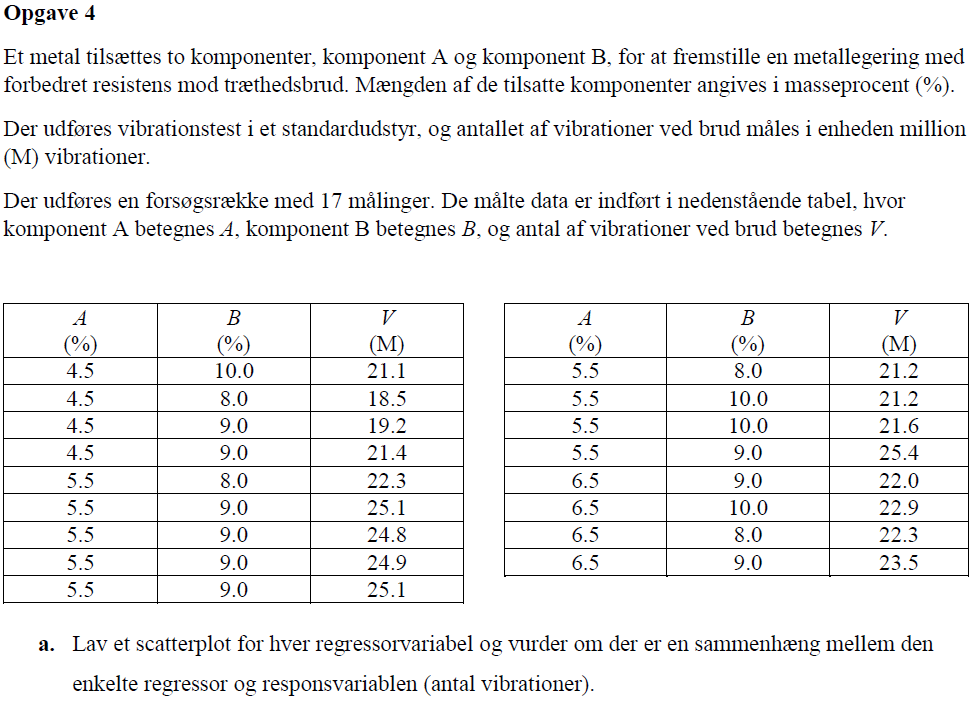

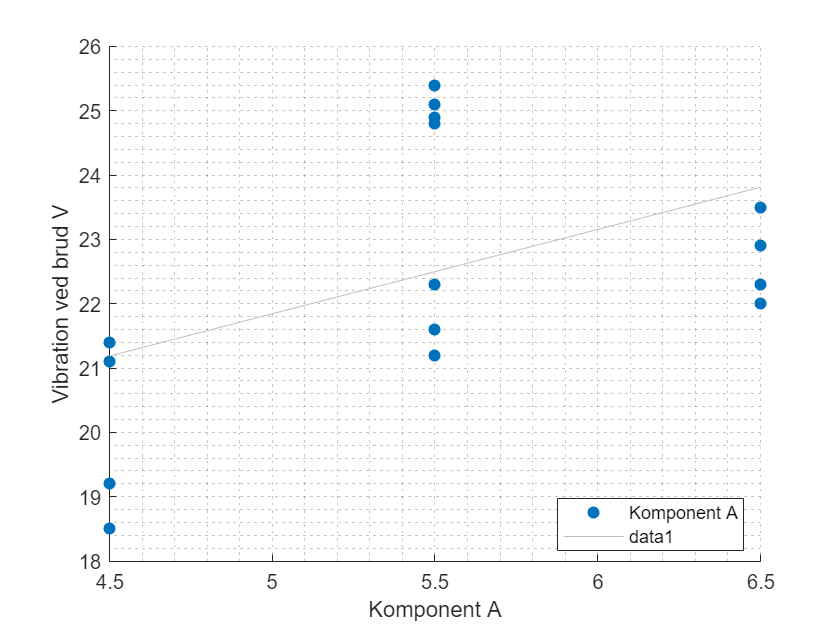

clear all
clf
format shortg
data = xlsread("Statestik\Eksamens sæt\21E\Data_M4STI1_2021E.xlsx", 'G:I');
A = data(:,1);
B = data(:,2);
V = data(:,3);

figure(1)
scatter(A, V, 'filled', DisplayName='Komponent A')
lsline
xlabel('Komponent A')
ylabel('Vibration ved brud V (M)')
grid('minor')
legend('Location','best')

Der ses en linær positiv sammenhæng med komponent A, dog med lidt spredte data.

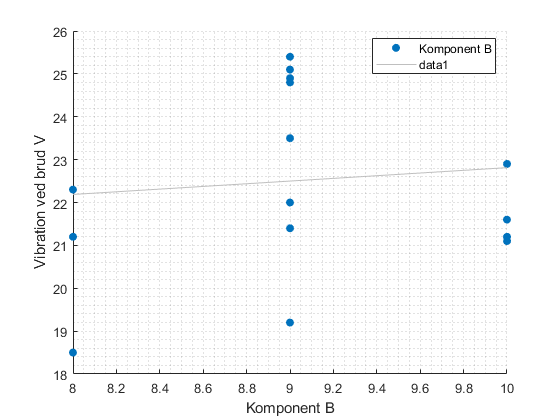


figure(2)
scatter(B, V, 'filled', DisplayName='Komponent B')
lsline
xlabel('Komponent B')
ylabel('Vibration ved brud V')
grid('minor')
legend('Location','best')

Der ses en linær positiv sammenhæng med komponent B, dog med lidt spredte data og i mindre grad end ved A.

b. Lav en multipel lineær regressionsanalyse, der beskriver antallet af vibrationer som funktion af tilsat mængde af komponent A og af komponent B. Opskriv regressionsligningen.

c. Vurder ud fra regressionsanalysens statistikker (f.eks. 𝑅2,𝐹 og p-værdi) om modellen beskriver observationerne godt. Anvend et signifikansniveau, 𝛼=0.05 ved din vurdering.

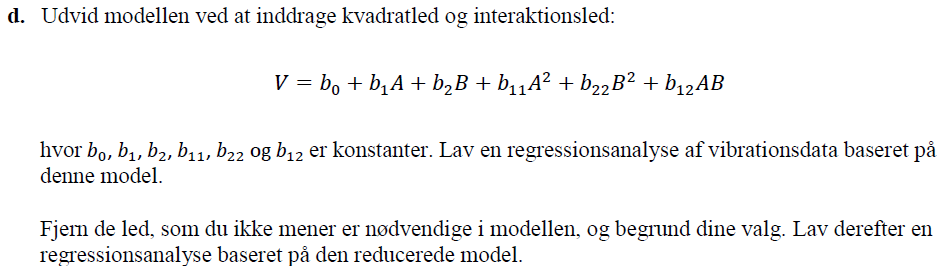

e. Opskriv ligningen for din foretrukne model.

f. Undersøg om der er ”unormale” datapunkter, dvs. løftestangspunkter, outliers, indflydelsespunkter. Svaret skal begrundes.

g. Lav et box-plot, et histogram og et normalfordelingsplot for de studentiserede residualer. Kommenter de tre plots.